## **Poisson's eq using Galerkin's Method.**

_____________________________________________________________________________

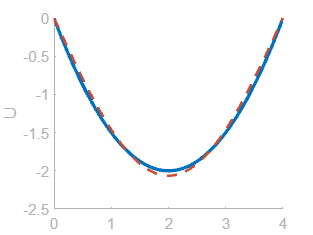

close all;

% Declare symbolic variable
syms u(x); % the state variable
syms f(x); % function in DE
syms As(i0,j0); % The Matrix A
syms bs(i0); % Matrix b
syms psi(x,i0); % basis functions
syms psidd(x,i0); % second derivative of basis functions
syms x
assume(i0,'real')
assume(j0,'real')
assume(i0>0)
assume(j0>0)

% Define the function
f(x) = -1;


% Define the ODE
ode = diff(u,x,2) == -f;

% Boundary Conditions
L=4; % Length of the domain
cond1 = u(0) == 0;
cond2 = u(L) == 0;
conds = [cond1 cond2];
uSol(x) = dsolve(ode,conds);
% uSol = simplify(uSol);


N=2 ;% Dimension of trial space


% Generate Basis Functions and required derivative


psi(x,i0)= (sin(i0*x*pi/L)); % Basis functions 
psidd(x,i0) = (diff(psi,x,2)); % Second derivatives

bs(i0) = int(-f*psi(x,i0),x,[0 L]); %
As(i0,j0) = int(psi(x,i0)*psidd(x,j0),x,[0 L]);

A = zeros(N,N);
b = zeros(N,1);
 for i1=1:N
     for j1=1:N
        A(i1,j1)=double(As(i1,j1)); 
        % double used to convert to number from symbolic variable
     end
     b(i1) = double(bs(i1));
 end
 

% The coeff vector for system
c=A\b; 

% psi = matlabFunction(psi);
% psidd = matlabFunction(psidd);

divs=100; % Number of divisions for domain for plotting
X = linspace(0,L,divs); % Define the domain

ps = zeros(divs,N);
psdd = zeros(divs,N); 
% Matrix whose each column contain value of a basis 
% function/derivative over the domain

for i2=1:N    
    ps(:,i2) = double(psi(X,i2));   
    psdd(:,i2) = double(psidd(X,i2));
end

psdd(isnan(psdd))=psdd(2,1); % Correction for 0 to the power 0


U= c'*ps'; % Trial Soltution
R= c'*psdd' + double(f(X));
R=round(R,7);
% Ploting Actual Solution and Trial solution
figure(1)
clf
hold on;

plot(X,double(uSol(X)),"Linewidth",2)
plot(X,U,'--',"Color",[0.8 0.3 0.2],"Linewidth",1.5)
ylabel("U")



FigCharacteristics;

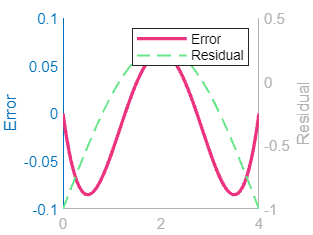


% Plotting Error
figure(2)
clf
hold on;

yyaxis left
ylabel("Error")
error = double(uSol(X)-U);
plot(X,round(error,7),'-',"Linewidth",2,"Color",[ 0.92 0.2 0.5])

yyaxis right
ylabel("Residual")
plot(X,R,'--',"Linewidth",1.2,"Color",[ 0.412 0.9020 0.5490]);
legend("Error","Residual")

FigCharacteristics;